clear; clc;
cvx_clear;

addpath './../classes'

% states for phase covariant cloning
s1 = [1;1]/sqrt(2);
s2 = [1; exp(1i*2*pi/3)]/sqrt(2);
s3 = [1; exp(1i*4*pi/3)]/sqrt(2);
states = [s1,s2,s3];


lambda = 0.5;

sdp = SDP_1to2_AsymmetricCloning(states, lambda);
[primal_optimum, J] = sdp.solvePrimal();
[dual_optimum,  ~] = sdp.solveDual();
kraus_ops = Utils.getKrausOperators(J,1,2);
[is_valid, completeness_error] = Utils.verifyKrausOperators( kraus_ops );
    
fprintf('\n=====================================================\n');

fprintf('Summary: ');

Summary: 

fprintf('-----------------------------------------------------\n');

-----------------------------------------------------


fprintf('Primal Solution      :      %.10f\n', primal_optimum);

Primal Solution      :      0.8535533901


fprintf('Dual Solution        :      %.10f\n', dual_optimum);

Dual Solution        :      0.8535533909


fprintf('Gap (Dual-Primal)    :      %.3e\n', (dual_optimum - primal_optimum));

Gap (Dual-Primal)    :      7.511e-10




fprintf('Number of Kraus op   :      %d\n', length(kraus_ops));

Number of Kraus op   :      2



if is_valid
    fprintf("Completness okay, tolerance: %.3e \n", completeness_error);
else
    fprintf("COMPLETNESS ERROR: %.3e\n", completeness_error);
end

Completness okay, tolerance: 1.630e-09 


fprintf('=====================================================\n');

for i = 1:length(kraus_ops)
  fprintf("Kraus Op %d\n", i );
  kraus_ops{i}
end

Kraus Op 1


ans =   -0.0000 + 0.0000i   0.0000 - 0.0000i
   0.5000 - 0.0000i  -0.0000 + 0.0000i
   0.5000 - 0.0000i  -0.0000 + 0.0000i
   0.0000 - 0.0000i   0.7071 + 0.0000i


Kraus Op 2


ans =    0.6837 - 0.1804i  -0.0000 - 0.0000i
   0.0000 + 0.0000i   0.4834 - 0.1276i
   0.0000 + 0.0000i   0.4834 - 0.1276i
   0.0000 + 0.0000i   0.0000 + 0.0000i



rho_in  = s1*s1';
rho_out = zeros(4, 4);        % Initialisierung der 4x4 Output-Matrix

for i = 1:length(kraus_ops)
    K = kraus_ops{i};         % Aktueller Kraus-Operator
    rho_out = rho_out + K * rho_in * K';
end

rho_out_A = PartialTrace( rho_out, [2], [2,2] );
rho_out_B = PartialTrace( rho_out, [1], [2,2] );

F_A = trace(rho_out_A * (s1*s1'))

F_A = 0.8536 - 0.0000i

F_B = trace(rho_out_B * (s1*s1'))

F_B = 0.8536 - 0.0000i

N = 50;
lambda_vec = linspace(0, 1, N);

F_A = zeros(1, N);
F_B = zeros(1, N);

% create phase covariant random state 
random_phi = rand * 2 * pi;
s_in = [1; exp(1i*random_phi)]/sqrt(2);
rho_in = s_in*s_in';

for idx = 1:N
    lambda = lambda_vec(idx);
    sdp = SDP_1to2_AsymmetricCloning(states, lambda);
    [primal_optimum, J] = sdp.solvePrimal();

    kraus_ops = Utils.getKrausOperators(J,1,2);

    rho_out = zeros(4, 4);        % Initialisierung der 4x4 Output-Matrix
    
    for i = 1:length(kraus_ops)
        K = kraus_ops{i};         % Aktueller Kraus-Operator
        rho_out = rho_out + K * rho_in * K';
    end
    
    rho_out_A = PartialTrace( rho_out, [2], [2,2] );
    rho_out_B = PartialTrace( rho_out, [1], [2,2] );

    F_A(idx) = round( trace(rho_out_A * rho_in), 12);
    F_B(idx) = round( trace(rho_out_B * rho_in), 12);
end

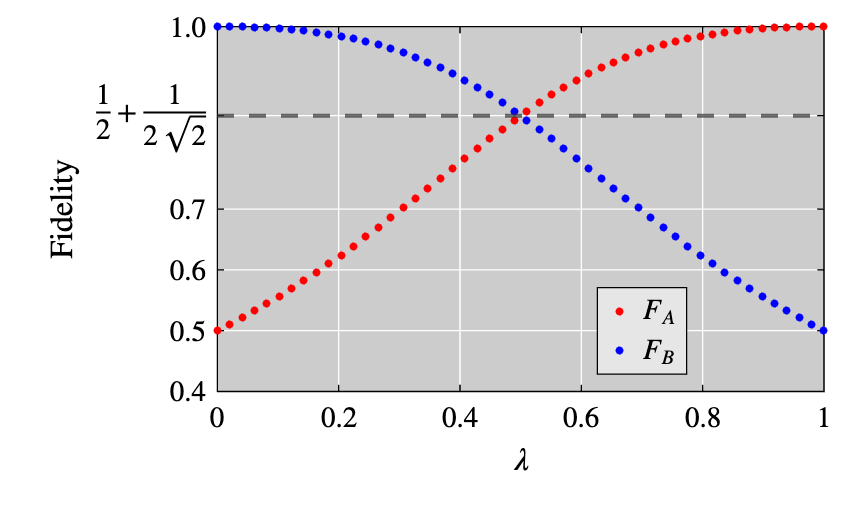

% Visualisierung mit LaTeX und weißem Hintergrund
figure('Color', 'w'); 

% --- PLOTTEN ---
plot(lambda_vec, F_A, 'ko', 'MarkerSize', 2,     ...
    'MarkerEdgeColor', 'r', ... 
    'MarkerFaceColor', 'r', ...
    'LineWidth', 1, 'DisplayName', '$F_A$'); hold on;

plot(lambda_vec, F_B, 'ko', 'MarkerSize', 2, ...
    'MarkerEdgeColor', 'b', ... 
    'MarkerFaceColor', 'b', ...
    'LineWidth', 1, 'DisplayName', '$F_B$'); 

% --- GRUNDEINSTELLUNGEN ---
ylim([0.4, 1.0]);
set(gca, 'FontName', 'Arial');
set(gca, 'Color', [0.8, 0.8, 0.8]);
grid on;
set(gca, 'GridColor', 'w', 'GridAlpha', 1);
xlabel('$\lambda$', 'Interpreter', 'latex', 'Color', 'k', 'FontSize', 11, 'FontName','Arial');
ylabel('Fidelity', 'Interpreter', 'latex', 'Color', 'k', 'FontSize', 11, 'FontName','Arial');

% Achsen-Tick-Labels Initialisierung
set(gca, 'XColor', [0 0 0], 'YColor', [0 0 0]); 
set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 11);

% --- DEIN NEUER ABSCHNITT: LINIE & BRUCH ---
target_val = (2 + sqrt(2)) / 4; 
%target_val = 5/6; 

% 1. Linie zeichnen
yline(target_val, '--', 'Color', [0.2, 0.2, 0.2], 'LineWidth', 1.5, 'HandleVisibility', 'off');

% 2. Ticks berechnen (wir entfernen Ticks zwischen 0.8 und 0.9, um Platz zu schaffen)
current_ticks = get(gca, 'YTick');
current_ticks(current_ticks > 0.7 & current_ticks < 0.95) = []; 
all_ticks = sort([current_ticks, target_val]);

% 3. LaTeX-Labels erstellen
tick_labels = arrayfun(@(v) sprintf('$%.1f$', v), all_ticks, 'UniformOutput', false);
[~, idx] = min(abs(all_ticks - target_val));
tick_labels{idx} = '$\frac{1}{2}+\frac{1}{2\sqrt{2}}$'; % Hier der LaTeX Bruch
%tick_labels{idx} = '$\frac{5}{6}$'; % Hier der LaTeX Bruch


% 4. Ticks anwenden
set(gca, 'YTick', all_ticks, 'YTickLabel', tick_labels);


% --- LEGENDE & LAYOUT ---
lgd = legend('show');
set(lgd, 'Interpreter', 'latex', 'Location', 'best', 'FontSize', 11, ...
         'Color', [0.9, 0.9, 0.9], 'TextColor', 'k', 'EdgeColor', 'k');

set(gca, 'Units', 'normalized');
set(gca, 'OuterPosition', [0, 0, 1, 1]); 
set(gca, 'InnerPosition', [0.25, 0.25, 0.7, 0.7]); 
set(gca, 'LooseInset', get(gca, 'TightInset'));

% --- EXPORT ---
exportgraphics(gcf, './figures/AsymmetricCovariantFidelities.jpg', 'Resolution', 300);